# Webinar Text Analytics Toolbox (Oct/2019)

Apresentado por:

Alberto Y Shimahara

## **Classificação de Texto com Bag of Words / Bag of N-Grams**

Desenvolvido por:

    - Daniel Vieira

Para esta demo, requer:

- MATLAB

- Deep Learning Toolbox

- Statistics & Machine Learning Toolbox

- Text Analytics Toolbox

- Parallel Computing Toolbox

#### load data (already "clean")

Dados pre-carregados e limpos a partir da fonte: [http://qwone.com/~jason/20Newsgroups/](http://qwone.com/~jason/20Newsgroups/)

Arquivo usado: Original 20 Newsgroups data set (20news-19997.tar.gz )

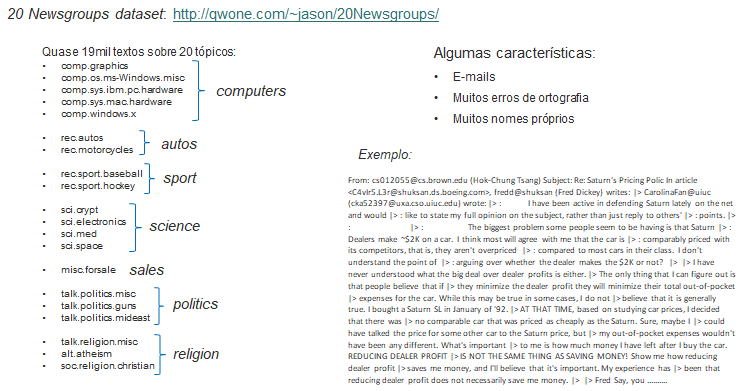

Para esta demos os dados foram extraidos do arquivo original e salvos em formato MATLAB para apresentação da demo.

Exemplo do texto limpo:

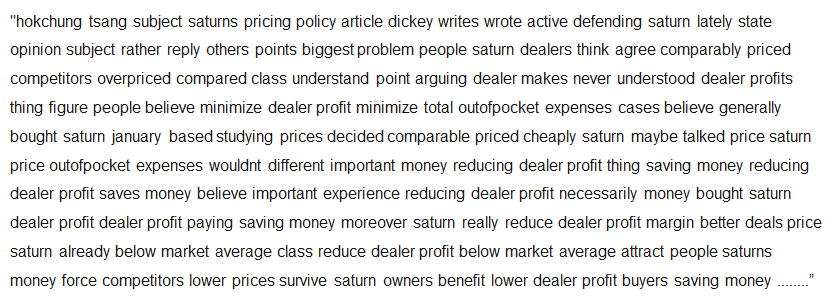

load('labels.mat') % categorias
load('T.mat') % Texto

#### Filter infrequent words

O modelo "Bag-of-Words" (saco-de-palavras) é uma representação simplificada  utilizada no processamento de linguagem natural e na recuperação de  informações.

B=bagOfWords(T); % guarda o numero de vezes que uma palavra aparece no texto
inds=sum(B.Counts,1)<5;
T=removeWords(T,inds); % remove palavras que apareceram menos de 5 vezes

enc=wordEncoding(T); % transforma em indices numericos

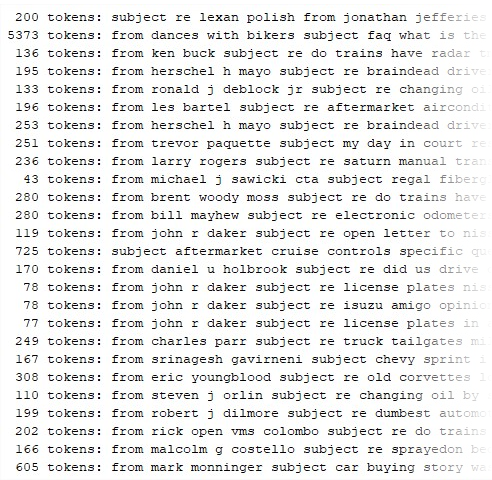

#### Balancing topics

Efetiva a reamostragem dos dados

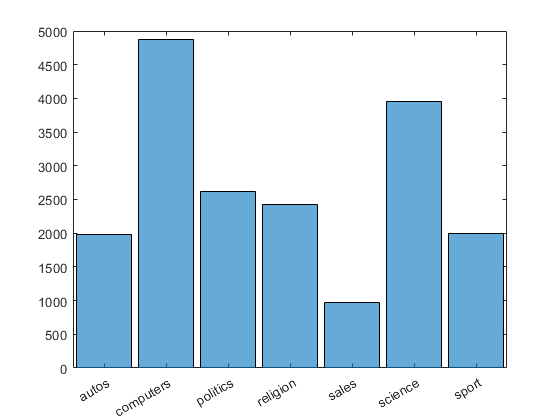

figure, histogram(labels)

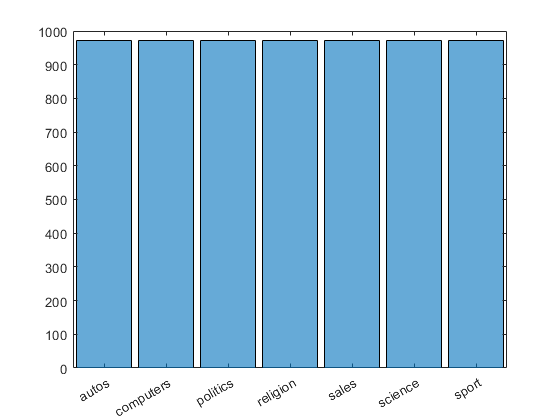

[g,gID]=findgroups(labels); % localiza os grupos e retorna quantidade
S=splitapply(@numel,labels,g);% divide os dados em grupos e aplica função
% que retorna numero de elementos
m=min(S);
inds=[];
for k=1:numel(gID)
    inds=[inds; randsample(find(g==k),m)];
end
T=T(inds);
labels=labels(inds);
figure, histogram(labels)

#### Partitioning

Gerando conjunto de dados para Treinamento e Validação

r=rand(size(T));
trainInds=r<=0.9;
validInds=r>0.9 & r<=0.95;
testInds=r>0.95;

txtTrain=T(trainInds);
topicTrain=labels(trainInds);
txtValid=T(validInds);
topicValid=labels(validInds);
txtTest=T(testInds);
topicTest=labels(testInds);

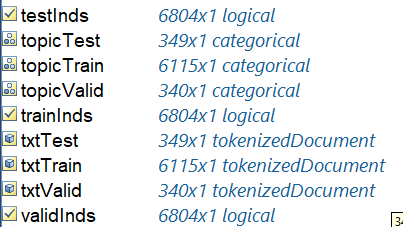

#### Truncating training/validation data

Separação dos dados dentro de limites 

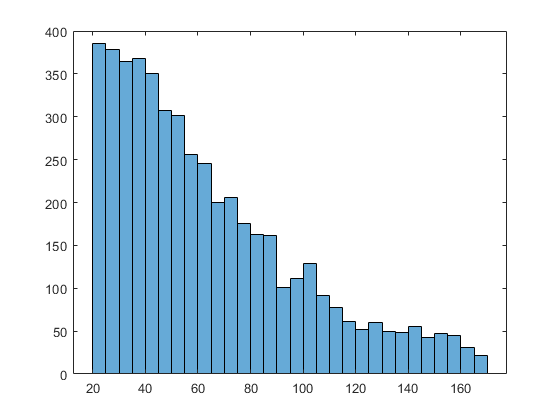

L=doclength(txtTrain);
figure, histogram(L)

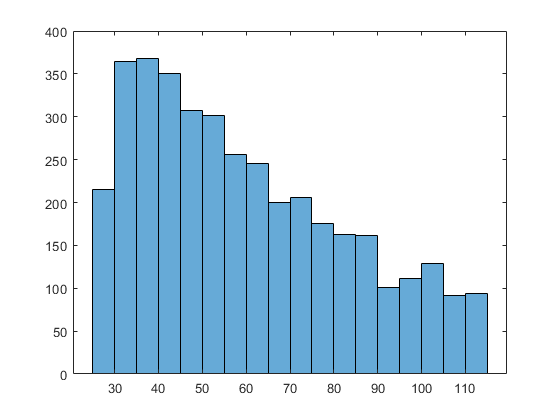


inds=L>prctile(L,10) & L<prctile(L,90);
txtTrain=txtTrain(inds);
topicTrain=topicTrain(inds);
L=L(inds);

[~,order]=sort(L,'ascend');
txtTrain=txtTrain(order);
topicTrain=topicTrain(order);
L=L(order);

figure, histogram(L)


XTrain=doc2sequence(enc,txtTrain,'Length',median(L)); % converte documentos para sequencia para uso em Deep Learning
XValid=doc2sequence(enc,txtValid,'Length',median(L));

#### Defining deep learning model and training settings

Efetiva parametros para Deep Learning, neste caso aplica-se Otimizador Adam.

[https://www.mathworks.com/help/deeplearning/ref/nnet.cnn.trainingoptionsadam.html?searchHighlight=adam&s_tid=doc_srchtitle](https://www.mathworks.com/help/deeplearning/ref/nnet.cnn.trainingoptionsadam.html?searchHighlight=adam&s_tid=doc_srchtitle)

inputSize = 1;
embeddingDimension = 64;
numWords = enc.NumWords;
numHiddenUnits = 32;
numClasses = numel(categories(labels));

layers=[sequenceInputLayer(inputSize)
    wordEmbeddingLayer(embeddingDimension,numWords)
    lstmLayer(numHiddenUnits,'OutputMode','last')
    dropoutLayer(0.3)
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

minibatch=32;
batchesPerEpoch=floor(numel(txtTrain)./minibatch);

opts=trainingOptions('adam', ...
    'MaxEpochs',100, ...
    'MiniBatchSize',minibatch, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.005, ...
    'ValidationData',{XValid,topicValid}, ...
    'ValidationPatience',5, ...
    'ValidationFrequency',batchesPerEpoch, ...
    'Plots','training-progress', ...
    'Verbose',false);

#### training model

Treina o modelo baseado nos parametros gerados acima

[net,trInfo]=trainNetwork(XTrain,topicTrain,layers,opts);

#### evaluating model accuracy

Classifica os dados usando a rede neural gerada

[classes,scores]=classify(net,doc2sequence(enc,txtTest));
% Create confusion matrix chart for classification problem
figure, confusionchart(topicTest,classes,'RowSummary','row-normalized','ColumnSummary','column-normalized')